% run eom calculations
create_EOMs = true

create_EOMs = logical
   1


if create_EOMs == false
    disp("To create dynamic equations change create_EOMs to true")
else
    %-------------------------
    % Symbols
    %-------------------------
    disp("%------------------------- Symbols -------------------------")
    
    syms g real % gravity [m/s^2]
    syms m0 m1 m2 real% masses [kg]
    syms r0 r1 r2 real% radius [m]
    syms l0 l1 l2 real% lenght [m]
    
    syms t tau0(t) tau1(t) tau2(t) % motor torques [Nm]
    assume([tau0(t) tau1(t) tau2(t)], 'real')
    
    syms t0 t1 t2 real % generalized variables
    
    syms b0 b1 b2 real % damping
    
    syms theta0(t) theta1(t) theta2(t) % angular variables [rad]
    assume([theta0(t) theta1(t) theta2(t)], 'real')
    
    syms q0 q1 q2 dq0 dq1 dq2 ddq0 ddq1 ddq2 real % generalized variables
    
    substitutions = [
        diff(theta0(t), t, t), ddq0;
        diff(theta1(t), t, t), ddq1;
        diff(theta2(t), t, t), ddq2;
        diff(theta0(t), t), dq0;
        diff(theta1(t), t), dq1;
        diff(theta2(t), t), dq2;
        theta0(t), q0;
        theta1(t), q1;
        theta2(t), q2;
        tau0(t), t0;
        tau1(t), t1;
        tau2(t), t2;
    ];

    % setting up the variable sets
    angular_variables = substitutions(:,1); % base variable set
    generalized_variables = substitutions(:,2); % generalized variable set
    
    %-------------------------
    % Inertia Cylinder
    %-------------------------
    disp("%------------------------- Inertia Cylinder -------------------------")
    
    % basic cylindrical inertia matrix with central mass point https://de.wikipedia.org/wiki/Liste_von_Tr%C3%A4gheitstensoren
    inertiaMatrix = @(m, l, r) [m*(3*r^2 + l^2)/12, 0, 0;
                                0, m*(3*r^2 + l^2)/12, 0;
                                0, 0, m*(r^2)/2];
    
    % setting up the inertia tensor matrices
    inertiaLink0 = inertiaMatrix(m0, l0, r0)
    inertiaLink1 = inertiaMatrix(m1, l1, r1)
    inertiaLink2 = inertiaMatrix(m2, l2, r2)
    
    %-------------------------
    % Translational Velocity of Mass in the World Frame
    %-------------------------
    disp("%------------------------- Translational Velocity of Mass -------------------------")
    
    % location of mass 0
    WF_PosM0 = [0; 0; l0/2];
    WF_PosM0 = rotationZAxis(theta0(t))*WF_PosM0
    % linear velocity of mass 0
    WF_TransVelM0 = diff( WF_PosM0, t);
    WF_TransVelM0
    
    % location of mass 1
    WF_PosM1 = [(l1*cos(theta1(t)))/2; 0; l0 + (l1*sin(theta1(t)))/2];
    WF_PosM1 = rotationZAxis(theta0(t))*WF_PosM1
    % linear velocity of mass 1
    WF_TransVelM1 = diff( WF_PosM1, t);
    WF_TransVelM1
    
    % location of mass 2
    WF_PosM2 = [l1*cos(theta1(t)) + (l2*cos(theta1(t)+theta2(t)))/2; 0; l0 + l1*sin(theta1(t)) + (l2*sin(theta1(t)+theta2(t)))/2];
    WF_PosM2 = rotationZAxis(theta0(t)) * WF_PosM2
    % linear velocity of mass 2
    WF_TransVelM2 = diff( WF_PosM2, t);
    WF_TransVelM2
    
    %-------------------------
    % Translation Energy
    %-------------------------
    disp("%------------------------- Translation Energy -------------------------")
    % calculate the translational energy
    KE_trans = translationalEnergy(m0, WF_TransVelM0) + translationalEnergy(m1, WF_TransVelM1) + translationalEnergy(m2, WF_TransVelM2)
    
    %-------------------------
    % Rotational Velocity of Mass in the Base Frame
    %-------------------------
    disp("%------------------------- Angular Velocity of Mass -------------------------")
    % The angular velocity is transformed to each link's local frame to simplify calculations.
    % This approach avoids the need to transform the inertia matrix.
    
    % transform dh
    transformLinkToLink0 =   [1,0,0;
                             0, 0,1;
                             0,-1,0];
    
    % local body frame already in alignment
    LF_angVelM0 = [0; 0; diff(theta0(t), t)]
    % rotate into body frame
    LF_angVelM1 = rotationYAxis(-theta1(t))*LF_angVelM0+transformLinkToLink0.'*[ 0; 0; diff(theta1(t))]
    LF_angVelM2 = rotationYAxis(-(theta1(t)+theta2(t)))*LF_angVelM0+transformLinkToLink0.'*[ 0; 0; diff(theta1(t)+theta2(t))]
    
    
    %-------------------------
    % Rotation Energy
    %-------------------------
    disp("%------------------------- Rotation Energy -------------------------")
    % calculate the rotational energy
    KE_rot = rotationEnergy(LF_angVelM0, inertiaLink0) + rotationEnergy(LF_angVelM1, inertiaLink1) + rotationEnergy(LF_angVelM2, inertiaLink2)
    
    %-------------------------
    % Kinetic Energy
    %-------------------------
    disp("%------------------------- Kinetic Energy -------------------------")
    
    KE_total = KE_trans + KE_rot
    
    %-------------------------
    % Potential Energy
    %-------------------------
    disp("%------------------------- Potential Energy -------------------------")
    % calculate the potential energy
    PE_total = potentialEnergy(g, m0, WF_PosM0(3)) + potentialEnergy(g, m1, WF_PosM1(3)) + potentialEnergy(g, m2, WF_PosM2(3))
    
    %-------------------------
    % Generalized forces
    %-------------------------
    disp("%------------------------- Generalized forces -------------------------")
    % Switching to generalized variables
    LF_angVelM0 = subs(LF_angVelM0, angular_variables, generalized_variables);
    LF_angVelM1 = subs(LF_angVelM1, angular_variables, generalized_variables);
    LF_angVelM2 = subs(LF_angVelM2, angular_variables, generalized_variables);
    % Setting up the torque matrix for joint 0
    tauM0Matrix = [...
                   0,                  0,                0,        0;          
                   0,                  0,         (-b1*dq1),    (t1);          
                (t0),          (-b0*dq0),                0,        0;   ];
    % Setting up the associated angular velocitys of joint 0
    angVelM0Matrix = [LF_angVelM0, LF_angVelM0, LF_angVelM0, LF_angVelM0];
    % Setting up the torque matrix for joint 1
    tauM1Matrix = [ ...
                   0,                0,            0,                  0; 
                (-t1),        (b1*dq1),         (t2),          (-b2*dq2);          
                   0,                0,            0,                  0;    ];
    % Setting up the associated angular velocitys of joint 1
    angVelM1Matrix = [LF_angVelM1, LF_angVelM1, LF_angVelM1, LF_angVelM1];
    % Setting up the torque matrix for joint 2
    tauM2Matrix = [ ...
                 0,                  0;            
              (-t2),          (b2*dq2);          
                 0,                  0;  ];
    % Setting up the associated angular velocitys of joint 2
    angVelM2Matrix = [LF_angVelM2, LF_angVelM2];
    
    % Setting up the torque matrix for all joint
    tauMatrix = [tauM0Matrix, tauM1Matrix, tauM2Matrix];
    % Setting up the associated angular velocitys of all joints
    angVelMatrix = [angVelM0Matrix, angVelM1Matrix, angVelM2Matrix];
    
    % calling the generalizedForces function to calculate the generalized forces
    Q2 = generalizedForces(tauMatrix, angVelMatrix, dq2);
    Q1 = generalizedForces(tauMatrix, angVelMatrix, dq1);
    Q0 = generalizedForces(tauMatrix, angVelMatrix, dq0);
    % Switching to base variables
    Q2 = subs(Q2, generalized_variables, angular_variables)
    Q1 = subs(Q1, generalized_variables, angular_variables)
    Q0 = subs(Q0, generalized_variables, angular_variables)
    
    %-------------------------
    % Define Lagrangian
    %-------------------------
    % calculate the lagrangian
    L = KE_total - PE_total
    % Lagrangian with generalized variables
    L = subs(L, angular_variables, generalized_variables);
    
    %-------------------------
    % d/dt(ϑtotaLagrangean/ϑqi_prime) - ϑtotalLagrangean/ϑqi = Qi
    %-------------------------
    % ϑtotalLagrangean/ϑqi
    dL_dq0 = diff( L, q0);
    dL_dq1 = diff( L, q1);
    dL_dq2 = diff( L, q2);
    % Switching to base variable set
    dL_dq0 = subs(dL_dq0, generalized_variables, angular_variables);
    dL_dq1 = subs(dL_dq1, generalized_variables, angular_variables);
    dL_dq2 = subs(dL_dq2, generalized_variables, angular_variables);
    
    % ϑtotaLagrangean/ϑqi_prime
    dL_ddq0 = diff( L, dq0);
    dL_ddq1 = diff( L, dq1);
    dL_ddq2 = diff( L, dq2);
    % Switching to base variable set (for differentiation with respect to t) 
    dL_ddq0 = subs(dL_ddq0, generalized_variables, angular_variables);
    dL_ddq1 = subs(dL_ddq1, generalized_variables, angular_variables);
    dL_ddq2 = subs(dL_ddq2, generalized_variables, angular_variables);
    
    % d/dt(ϑtotaLagrangean/ϑqi_prime)
    dLddq0_dt = diff(dL_ddq0, t);
    dLddq1_dt = diff(dL_ddq1, t);
    dLddq2_dt = diff(dL_ddq2, t);
    
    % equations of motion
    EOM0 = simplify(dLddq0_dt - dL_dq0) == Q0;
    EOM1 = simplify(dLddq1_dt - dL_dq1) == Q1;
    EOM2 = simplify(dLddq2_dt - dL_dq2) == Q2;
    
    % try to simplify
    EOM0 = simplify(EOM0);
    EOM1 = simplify(EOM1);
    EOM2 = simplify(EOM2);
    
    % switching to generalized variable set
    EOM0 = subs(EOM0, angular_variables, generalized_variables);
    EOM1 = subs(EOM1, angular_variables, generalized_variables);
    EOM2 = subs(EOM2, angular_variables, generalized_variables);
    EOM = [EOM0; EOM1; EOM2]
    
    % solving for acceleration in the context of forward dynamics
    %S = solve([EOM0, EOM1, EOM2], [ddq0, ddq1, ddq2]);
    %EOM_ddq = [S.ddq0; S.ddq1; S.ddq2];
    
    % solving for torque in the context of inverse dynamics
    S = solve([EOM0, EOM1, EOM2], [t0, t1, t2]);
    EOM_tau0 = S.t0
    EOM_tau1 = S.t1
    EOM_tau2 = S.t2
end

%------------------------- Symbols -------------------------


%------------------------- Inertia Cylinder -------------------------


$$inertiaLink0 = \left(\begin{array}{ccc} \frac{m_{0}\,\left({l_{0}}^{2}+3\,{r_{0}}^{2}\right)}{12} & 0 & 0\\ 0 & \frac{m_{0}\,\left({l_{0}}^{2}+3\,{r_{0}}^{2}\right)}{12} & 0\\ 0 & 0 & \frac{m_{0}\,{r_{0}}^{2}}{2} \end{array}\right)$$

$$inertiaLink1 = \left(\begin{array}{ccc} \frac{m_{1}\,\left({l_{1}}^{2}+3\,{r_{1}}^{2}\right)}{12} & 0 & 0\\ 0 & \frac{m_{1}\,\left({l_{1}}^{2}+3\,{r_{1}}^{2}\right)}{12} & 0\\ 0 & 0 & \frac{m_{1}\,{r_{1}}^{2}}{2} \end{array}\right)$$

$$inertiaLink2 = \left(\begin{array}{ccc} \frac{m_{2}\,\left({l_{2}}^{2}+3\,{r_{2}}^{2}\right)}{12} & 0 & 0\\ 0 & \frac{m_{2}\,\left({l_{2}}^{2}+3\,{r_{2}}^{2}\right)}{12} & 0\\ 0 & 0 & \frac{m_{2}\,{r_{2}}^{2}}{2} \end{array}\right)$$

%------------------------- Translational Velocity of Mass -------------------------


$$WF\_PosM0 = \left(\begin{array}{c} 0\\ 0\\ \frac{l_{0}}{2} \end{array}\right)$$

$$WF\_TransVelM0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$WF\_PosM1 = \left(\begin{array}{c} \frac{l_{1}\,\cos\left(\theta_{0}\left(t\right)\right)\,\cos\left(\theta_{1}\left(t\right)\right)}{2}\\ \frac{l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{0}\left(t\right)\right)}{2}\\ l_{0}+\frac{l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)}{2} \end{array}\right)$$

$$WF\_TransVelM1 = \left(\begin{array}{c} -\frac{l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{0}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{2}-\frac{l_{1}\,\cos\left(\theta_{0}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{2}\\ \frac{l_{1}\,\cos\left(\theta_{0}\left(t\right)\right)\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{2}-\frac{l_{1}\,\sin\left(\theta_{0}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{2}\\ \frac{l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{2} \end{array}\right)$$

$$WF\_PosM2 = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0}\left(t\right)\right)\,\sigma_{1}\\ \sin\left(\theta_{0}\left(t\right)\right)\,\sigma_{1}\\ l_{0}+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+\frac{l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+\frac{l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)}{2} \end{array}$$

$$WF\_TransVelM2 = \begin{array}{l} \left(\begin{array}{c} -\cos\left(\theta_{0}\left(t\right)\right)\,\sigma_{2}-\sin\left(\theta_{0}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)\\ \cos\left(\theta_{0}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)-\sin\left(\theta_{0}\left(t\right)\right)\,\sigma_{2}\\ \frac{l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\sigma_{3}}{2}+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+\frac{l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)}{2}\\ \sigma_{2}=\frac{l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\sigma_{3}}{2}+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \sigma_{3}=\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}$$

%------------------------- Translation Energy -------------------------


%------------------------- Angular Velocity of Mass -------------------------


$$LF\_angVelM0 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{0}\left(t\right) \end{array}\right)$$

$$LF\_angVelM1 = \left(\begin{array}{c} -\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)\\ -\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{0}\left(t\right) \end{array}\right)$$

$$LF\_angVelM2 = \left(\begin{array}{c} -\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)\\ -\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{0}\left(t\right) \end{array}\right)$$

%------------------------- Rotation Energy -------------------------


$$KE\_rot = \begin{array}{l} \frac{m_{1}\,\sigma_{5}\,\sigma_{3}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{24}+\frac{m_{2}\,\sigma_{2}\,\left(\frac{\sigma_{5}}{2}+\frac{\bar{\frac{\partial }{\partial t}\theta_{2}\left(t\right)}}{2}\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}{12}+\frac{m_{0}\,{r_{0}}^{2}\,\sigma_{1}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{4}+\frac{m_{2}\,\sigma_{1}\,{\sin\left(\sigma_{4}\right)}^{2}\,\sigma_{2}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{24}+\frac{m_{1}\,{r_{1}}^{2}\,\sigma_{1}\,{\cos\left(\theta_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{4}+\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{1}\,{\cos\left(\sigma_{4}\right)}^{2}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{4}+\frac{m_{1}\,\sigma_{1}\,{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{3}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)}{24}\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}\theta_{0}\left(t\right)}\\ \sigma_{2}={l_{2}}^{2}+3\,{r_{2}}^{2}\\ \sigma_{3}={l_{1}}^{2}+3\,{r_{1}}^{2}\\ \sigma_{4}=\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\\ \sigma_{5}=\bar{\frac{\partial }{\partial t}\theta_{1}\left(t\right)} \end{array}$$

%------------------------- Kinetic Energy -------------------------


%------------------------- Potential Energy -------------------------


$$PE\_total = g\,m_{1}\,\left(l_{0}+\frac{l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)}{2}\right)+g\,m_{2}\,\left(l_{0}+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+\frac{l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)}{2}\right)+\frac{g\,l_{0}\,m_{0}}{2}$$

%------------------------- Generalized forces -------------------------


$$Q2 = \tau_{2}\left(t\right)-b_{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)$$

$$Q1 = \tau_{1}\left(t\right)-b_{1}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

$$Q0 = \tau_{0}\left(t\right)-b_{0}\,\frac{\partial }{\partial t}\theta_{0}\left(t\right)$$

$$EOM\_tau0 = \begin{array}{l} b_{0}\,{\mathrm{dq}}_{0}+\frac{{\mathrm{ddq}}_{0}\,m_{0}\,{r_{0}}^{2}}{2}+\frac{3\,{\mathrm{ddq}}_{0}\,m_{1}\,{r_{1}}^{2}}{8}+\frac{3\,{\mathrm{ddq}}_{0}\,m_{2}\,{r_{2}}^{2}}{8}+\frac{{\mathrm{ddq}}_{0}\,{l_{1}}^{2}\,m_{1}}{6}+\frac{{\mathrm{ddq}}_{0}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{\mathrm{ddq}}_{0}\,{l_{2}}^{2}\,m_{2}}{6}+\frac{{\mathrm{ddq}}_{0}\,{l_{1}}^{2}\,m_{1}\,\cos\left(2\,q_{1}\right)}{12}+\frac{{\mathrm{ddq}}_{0}\,{l_{1}}^{2}\,m_{2}\,\cos\left(2\,q_{1}\right)}{2}+\frac{{\mathrm{ddq}}_{0}\,m_{1}\,{r_{1}}^{2}\,\cos\left(2\,q_{1}\right)}{8}+\frac{{\mathrm{ddq}}_{0}\,{l_{2}}^{2}\,m_{2}\,\cos\left(\sigma_{2}\right)}{12}+\frac{{\mathrm{ddq}}_{0}\,m_{2}\,{r_{2}}^{2}\,\cos\left(\sigma_{2}\right)}{8}+\frac{{\mathrm{ddq}}_{0}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(2\,q_{1}+q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{1}\,\sin\left(2\,q_{1}\right)}{6}-{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{2}\,\sin\left(2\,q_{1}\right)-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{1}\,m_{1}\,{r_{1}}^{2}\,\sin\left(2\,q_{1}\right)}{4}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{1}\,{l_{2}}^{2}\,m_{2}\,\sin\left(\sigma_{2}\right)}{6}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{2}\,{l_{2}}^{2}\,m_{2}\,\sin\left(\sigma_{2}\right)}{6}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{1}\,m_{2}\,{r_{2}}^{2}\,\sin\left(\sigma_{2}\right)}{4}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{2}\,m_{2}\,{r_{2}}^{2}\,\sin\left(\sigma_{2}\right)}{4}+\frac{{\mathrm{ddq}}_{0}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}-{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sigma_{1}-\frac{{\mathrm{dq}}_{0}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sigma_{1}}{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{1}+q_{2}\right)\\ \sigma_{2}=2\,q_{1}+2\,q_{2} \end{array}$$

$$EOM\_tau1 = \begin{array}{l} b_{1}\,{\mathrm{dq}}_{1}+\frac{{\mathrm{ddq}}_{1}\,m_{1}\,{r_{1}}^{2}}{4}+\frac{{\mathrm{ddq}}_{1}\,m_{2}\,{r_{2}}^{2}}{4}+\frac{{\mathrm{ddq}}_{2}\,m_{2}\,{r_{2}}^{2}}{4}+\frac{{\mathrm{ddq}}_{1}\,{l_{1}}^{2}\,m_{1}}{3}+{\mathrm{ddq}}_{1}\,{l_{1}}^{2}\,m_{2}+\frac{{\mathrm{ddq}}_{1}\,{l_{2}}^{2}\,m_{2}}{3}+\frac{{\mathrm{ddq}}_{2}\,{l_{2}}^{2}\,m_{2}}{3}+\frac{g\,l_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}+g\,l_{1}\,m_{2}\,\cos\left(q_{1}\right)+\frac{{{\mathrm{dq}}_{0}}^{2}\,{l_{1}}^{2}\,m_{1}\,\sin\left(2\,q_{1}\right)}{12}+\frac{{{\mathrm{dq}}_{0}}^{2}\,{l_{1}}^{2}\,m_{2}\,\sin\left(2\,q_{1}\right)}{2}+\frac{{{\mathrm{dq}}_{0}}^{2}\,m_{1}\,{r_{1}}^{2}\,\sin\left(2\,q_{1}\right)}{8}+\frac{{{\mathrm{dq}}_{0}}^{2}\,{l_{2}}^{2}\,m_{2}\,\sigma_{1}}{12}+\frac{{{\mathrm{dq}}_{0}}^{2}\,m_{2}\,{r_{2}}^{2}\,\sigma_{1}}{8}-\frac{{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{0}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(2\,q_{1}+q_{2}\right)}{2}+{\mathrm{ddq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)+\frac{{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)}{2}-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{1}+2\,q_{2}\right) \end{array}$$

$$EOM\_tau2 = \begin{array}{l} b_{2}\,{\mathrm{dq}}_{2}+\frac{{\mathrm{ddq}}_{1}\,m_{2}\,{r_{2}}^{2}}{4}+\frac{{\mathrm{ddq}}_{2}\,m_{2}\,{r_{2}}^{2}}{4}+\frac{{\mathrm{ddq}}_{1}\,{l_{2}}^{2}\,m_{2}}{3}+\frac{{\mathrm{ddq}}_{2}\,{l_{2}}^{2}\,m_{2}}{3}+\frac{g\,l_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{0}}^{2}\,{l_{2}}^{2}\,m_{2}\,\sigma_{1}}{12}+\frac{{{\mathrm{dq}}_{0}}^{2}\,m_{2}\,{r_{2}}^{2}\,\sigma_{1}}{8}+\frac{{{\mathrm{dq}}_{0}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{0}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(2\,q_{1}+q_{2}\right)}{4}+\frac{{\mathrm{ddq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{1}+2\,q_{2}\right) \end{array}$$

% Create a new matlab function block
create_eom_block = false;
if(true==create_eom_block)
    MODEL_NAME = 'Griesche_Nico_92100873_DLBROPIRC01_INVERSE_DYNAMICS_BLOCK';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME,0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)
    matlabFunctionBlock([MODEL_NAME, '/INVERSE_DYNAMICS_BLOCK'], EOM_tau0, EOM_tau1, EOM_tau2, 'optimize', false, 'Outputs', {'tau0', 'tau1', 'tau2'});
else
    disp("To create a new eom function block change create_EOMs and create_eom_block to true. Run whole simulation")
end

To create a new eom function block change create_EOMs and create_eom_block to true. Run whole simulation


% Creating a duplicate of the model for inverse kinematics analysis
IKModel = robotics.RigidBodyTree('DataFormat','column','MaxNumBodies',4);

% Comments for the first section body0 are equally valid for the other sections
% body0
% Initialize a rigid body named "link0" for the robotic arm.
body0 = robotics.RigidBody('link0');
% Create a revolute joint.
joint0 = robotics.Joint('joint0', 'revolute');
% Set the home position of the joint.
joint0.HomePosition = 0;
% Set the motion range of the joint.
joint0.PositionLimits = [-pi, pi];
% Create a transformation matrix for the joint position.
tform0 = trvec2tform([0,0,0]);
% Apply the transformation matrix to the joint.
setFixedTransform(joint0, tform0);
% Assign the created joint.
body0.Joint = joint0;
% Add 'link0' to the robot model, connecting it to the base.
addBody(IKModel, body0, 'base');

% body1
body1 = robotics.RigidBody('link1');
joint1 = robotics.Joint('joint1', 'revolute');
% applying transformations according to DH convention
joint1.JointAxis = [0 0 1];
tform1 = trvec2tform([0,0,0.5]) * eul2tform([0, -7*pi/9, pi/2]);
setFixedTransform(joint1, tform1);
joint1.HomePosition = 0;
joint1.PositionLimits = [-2*pi/3, 0];
body1.Joint = joint1;
addBody(IKModel, body1, 'link0');

% body2
body2 = robotics.RigidBody('link2');
joint2 = robotics.Joint('joint2', 'revolute');
% applying transformations according to DH convention
joint2.JointAxis = [0 0 1];
tform2 = trvec2tform([1, 0, 0]);
tform2 = trvec2tform([1,0, 0]) * eul2tform([-7*pi/9, 0, 0]);
setFixedTransform(joint2, tform2);
joint2.HomePosition = 0;
joint2.PositionLimits = [0, 7*pi/9];
body2.Joint = joint2;
addBody(IKModel, body2, 'link1');

% body3
body3 = robotics.RigidBody('endeffector');
joint3 = robotics.Joint('joint3', 'fixed');
tform3 = trvec2tform([1.5,0,0]);
setFixedTransform(joint3, tform3);
body3.Joint = joint3;
addBody(IKModel, body3, 'link2');

%show(IKModel)

% Initialize the Inverse Kinematics solver with the robot model
ik = robotics.InverseKinematics('RigidBodyTree', IKModel);
% Set the solver algorithm to BFGS Gradient Projection
% Options -----> 'BFGSGradientProjection';  'LevenbergMarquardt';
ik.SolverAlgorithm = 'BFGSGradientProjection';
% Disable random restarts to ensure consistent initial guesses lead to solution
ik.SolverParameters.AllowRandomRestart = false;
% Define the target orientation for the end effector as a quaternion
targetOrientation = [1, 0, 0, 0];
% Set the weights for position and orientation
targetWeights = [0 0 0 1 1 1];
% Use the robot model's home configuration as the initial guess for the solver
initialGuess = IKModel.homeConfiguration;
% Specify the name of the end effector in the robot model
endEffector = 'endeffector';

% Define target positions for the end effector
% Important! If u change the number of waypoints, it is probably necessary
% to change the peak velocity of the trapezprofil.
positionMatrix = [...
      733e-3,   0,  114e-3;
       0,   2,  0];

% Initialize a matrix to store the angular solutions for each target position
angularMatrix = zeros(2,3);

% Loop over each target position to find the corresponding joint angles
for i = 1:size(positionMatrix, 1)
    % Create the target transformation matrix from position and orientation
    targetTransform = trvec2tform(positionMatrix(i,:)) * quat2tform(targetOrientation);
    % Solve the inverse kinematics problem for the current target
    [solution, solInfo] = ik(endEffector, targetTransform, targetWeights, initialGuess);
    % Store the solution (joint angles) in the angular matrix
    for j = 1:numel(IKModel.homeConfiguration)
        angularMatrix(i,j) = solution(j);
    end
    % Update the initial guess to the current solution for the next iteration
    initialGuess = solution;
end

angularMatrix = angularMatrix(:,1:3)

angularMatrix =     0.0000   -1.2040         0
    1.5708   -1.9325    1.2125



% % testing the 2m condition
% config = [1.5708;	-1.9325;	1.2125];
% clf;
% show(IKModel, config);

trapezPosition =          0         0         0
    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0001
    0.0001   -0.0001    0.0001
    0.0001   -0.0001    0.0002
    0.0002   -0.0002    0.0002
    0.0003   -0.0002    0.0003
    0.0003   -0.0003    0.0004
    0.0004   -0.0004    0.0006


numberOfTimePoints =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


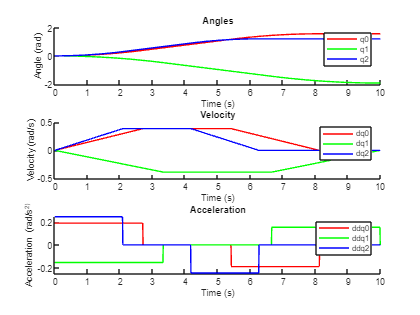

trapezPosition =          0         0         0
    0.0000   -0.0000    0.0000
    0.0000   -0.0001    0.0001
    0.0001   -0.0002    0.0001
    0.0001   -0.0003    0.0002
    0.0001   -0.0004    0.0004
    0.0002   -0.0006    0.0005
    0.0003   -0.0009    0.0007
    0.0004   -0.0011    0.0009
    0.0005   -0.0014    0.0012


numberOfTimePoints =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


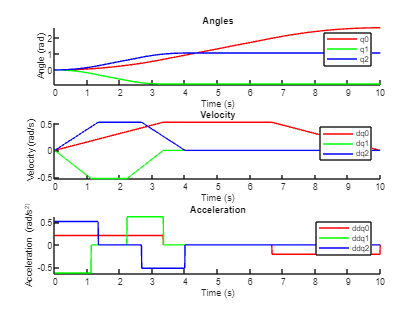

trapezPosition =          0         0         0
   -0.0000   -0.0000    0.0000
   -0.0001   -0.0001    0.0001
   -0.0003   -0.0003    0.0003
   -0.0005   -0.0005    0.0005
   -0.0008   -0.0008    0.0008
   -0.0011   -0.0011    0.0011
   -0.0016   -0.0016    0.0016
   -0.0020   -0.0020    0.0020
   -0.0026   -0.0026    0.0026


numberOfTimePoints =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


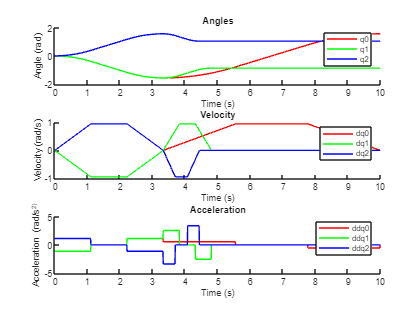

for i = 1:3
    if i == 1
        % Testing 2m Condition
        %angularMatrix = [0,0,0; 0, 0.5110, -1.2310];
        angularMatrix = [0,0,0; 1.5708,	-1.9325,	1.2125];
        peakVelocity = 2*findMaxDifference(angularMatrix)/10;
    elseif i == 2
        % Rotation to the (right) positiv q0
        angularMatrix = [0,0,0; pi/1.2, -5*pi/18, 5*pi/15];
        peakVelocity = 2*findMaxDifference(angularMatrix)/10;
    else
        % Rotation to the (left) negativ q0, and a return to the positiv q0
        angularMatrix = [0,0,0; -pi/2, -pi/2, pi/2; pi/2, -5*pi/18, 5*pi/15];
        peakVelocity = 6*findMaxDifference(angularMatrix)/10;
    end

% Reference to MATLAB documentation for designing trajectories with velocity limits using a trapezoidal velocity profile.
% https://de.mathworks.com/help/robotics/ug/design-a-trajectory-with-velocity-limits-using-a-trapezoidal-velocity-profile.html
% Trapez Profil PeakVelocity > (2*s/endtime) 0.16
[trapezPosition, trapezVelocity, trapezAcceleration, tSamples, pp] = trapveltraj(angularMatrix', 1000, 'PeakVelocity', peakVelocity);
trapezPosition = trapezPosition'
trapezVelocity = trapezVelocity';
trapezAcceleration = trapezAcceleration';

% Create a series of time points based on the desired total duration.
desiredDuration = 10; 
numberOfTimePoints = linspace(0, desiredDuration, size(trapezPosition, 1))

figure;
subplot(3,1,1); % Positionen Plot
hold on;
plot(numberOfTimePoints, trapezPosition(:,1), 'r-', 'DisplayName', 'q0');
plot(numberOfTimePoints, trapezPosition(:,2), 'g-', 'DisplayName', 'q1');
plot(numberOfTimePoints, trapezPosition(:,3), 'b-', 'DisplayName', 'q2');
hold off;
title('Angles');
xlabel('Time (s)');
ylabel('Angle (rad)');
legend;

subplot(3,1,2); % Velocity Plot
hold on;
plot(numberOfTimePoints, trapezVelocity(:,1), 'r-', 'DisplayName', 'dq0');
plot(numberOfTimePoints, trapezVelocity(:,2), 'g-', 'DisplayName', 'dq1');
plot(numberOfTimePoints, trapezVelocity(:,3), 'b-', 'DisplayName', 'dq2');
hold off;
title('Velocity');
xlabel('Time (s)');
ylabel('Velocity (rad/s)');
legend;

subplot(3,1,3); % Acceleration Plot
hold on;
plot(numberOfTimePoints, trapezAcceleration(:,1), 'r-', 'DisplayName', 'ddq0');
plot(numberOfTimePoints, trapezAcceleration(:,2), 'g-', 'DisplayName', 'ddq1');
plot(numberOfTimePoints, trapezAcceleration(:,3), 'b-', 'DisplayName', 'ddq2');
hold off;
title('Acceleration');
xlabel('Time (s)');
ylabel('Acceleration (rad/s^2)');
legend;

    if i == 1
        % Create time series objects for simulink simulation.
        ts1_q0_pos = timeseries(trapezPosition(:,1), numberOfTimePoints);
        ts1_q1_pos = timeseries(trapezPosition(:,2), numberOfTimePoints);
        ts1_q2_pos = timeseries(trapezPosition(:,3), numberOfTimePoints);
        
        ts1_q0_vel = timeseries(trapezVelocity(:,1), numberOfTimePoints);
        ts1_q1_vel = timeseries(trapezVelocity(:,2), numberOfTimePoints);
        ts1_q2_vel = timeseries(trapezVelocity(:,3), numberOfTimePoints);
        
        ts1_q0_acc = timeseries(trapezAcceleration(:,1), numberOfTimePoints);
        ts1_q1_acc = timeseries(trapezAcceleration(:,2), numberOfTimePoints);
        ts1_q2_acc = timeseries(trapezAcceleration(:,3), numberOfTimePoints);
    elseif i == 2
        % Create time series objects for simulink simulation.
        ts2_q0_pos = timeseries(trapezPosition(:,1), numberOfTimePoints);
        ts2_q1_pos = timeseries(trapezPosition(:,2), numberOfTimePoints);
        ts2_q2_pos = timeseries(trapezPosition(:,3), numberOfTimePoints);
        
        ts2_q0_vel = timeseries(trapezVelocity(:,1), numberOfTimePoints);
        ts2_q1_vel = timeseries(trapezVelocity(:,2), numberOfTimePoints);
        ts2_q2_vel = timeseries(trapezVelocity(:,3), numberOfTimePoints);
        
        ts2_q0_acc = timeseries(trapezAcceleration(:,1), numberOfTimePoints);
        ts2_q1_acc = timeseries(trapezAcceleration(:,2), numberOfTimePoints);
        ts2_q2_acc = timeseries(trapezAcceleration(:,3), numberOfTimePoints);
    else
        % Create time series objects for simulink simulation.
        ts3_q0_pos = timeseries(trapezPosition(:,1), numberOfTimePoints);
        ts3_q1_pos = timeseries(trapezPosition(:,2), numberOfTimePoints);
        ts3_q2_pos = timeseries(trapezPosition(:,3), numberOfTimePoints);
        
        ts3_q0_vel = timeseries(trapezVelocity(:,1), numberOfTimePoints);
        ts3_q1_vel = timeseries(trapezVelocity(:,2), numberOfTimePoints);
        ts3_q2_vel = timeseries(trapezVelocity(:,3), numberOfTimePoints);
        
        ts3_q0_acc = timeseries(trapezAcceleration(:,1), numberOfTimePoints);
        ts3_q1_acc = timeseries(trapezAcceleration(:,2), numberOfTimePoints);
        ts3_q2_acc = timeseries(trapezAcceleration(:,3), numberOfTimePoints);
    end
end

try
    positionErrorRadians = out.positionErrorRadians;
    positionErrorCartesian = out.positionErrorCartesian;
    positionCartesian = out.positionCartesian;
catch ME
    disp("Run the simulation file")
end

Run the simulation file



% Check if the variables are present in the Workspace
if exist('positionErrorRadians', 'var') && exist('positionErrorCartesian', 'var') && exist('positionCartesian', 'var')
    % Plot for radial position error
    figure;
    plot(positionErrorRadians.Time, positionErrorRadians.Data);
    title('Radial Position Error');
    xlabel('Time (s)');
    ylabel('Error (Radians)');
    grid on;
    % Calculate the average radial position error
    meanPositionErrorRadians = mean(positionErrorRadians.Data);
    disp(['Average radial position error: ', num2str(meanPositionErrorRadians)]);

    % Reshape data for positionErrorCartesian
    positionErrorCartesian.Data = squeeze(positionErrorCartesian.Data);
    % Plot for cartesian position error
    figure;
    plot(positionErrorCartesian.Time, positionErrorCartesian.Data(1, :), 'r', ...
         positionErrorCartesian.Time, positionErrorCartesian.Data(2, :), 'g', ...
         positionErrorCartesian.Time, positionErrorCartesian.Data(3, :), 'b');
    title('Cartesian Position Error');
    xlabel('Time (s)');
    ylabel('Error (mm)');
    grid on;
    % Calculate the average cartesian position error
    % Calculate the average cartesian position error for each dimension
    meanCartesianErrorX = mean(positionErrorCartesian.Data(1, :));
    meanCartesianErrorY = mean(positionErrorCartesian.Data(2, :));
    meanCartesianErrorZ = mean(positionErrorCartesian.Data(3, :));
    % Calculate maximum cartesian position error for each dimension
    maxCartesianErrorX = max(abs(positionErrorCartesian.Data(1, :)));
    maxCartesianErrorY = max(abs(positionErrorCartesian.Data(2, :)));
    maxCartesianErrorZ = max(abs(positionErrorCartesian.Data(3, :)));
    % Retrieve and display the last values from each dimension
    disp(['Average Cartesian errors (X, Y, Z): ', num2str([meanCartesianErrorX, meanCartesianErrorY, meanCartesianErrorZ])]);
    disp(['Maximum Cartesian errors (X, Y, Z): ', num2str([maxCartesianErrorX, maxCartesianErrorY, maxCartesianErrorZ])]);

    % Reshape data for positionCartesian (This should be done only once if the data structure is consistent)
    positionCartesian.Data = squeeze(positionCartesian.Data);
    % Plot for cartesian position
    figure;
    plot(positionCartesian.Time, positionCartesian.Data(1, :), 'r', ...
         positionCartesian.Time, positionCartesian.Data(2, :), 'g', ...
         positionCartesian.Time, positionCartesian.Data(3, :), 'b');
    title('Cartesian Position');
    xlabel('Time (s)');
    ylabel('Position (mm)');
    grid on;
else
    disp('One or more of the required variables are not present in the Workspace.');
end

One or more of the required variables are not present in the Workspace.


% Randomize values
r0 = 0.2;
l0 = 0.5;
m0 = 20;
r0 = apply_variation(r0)

r0 = 0.1932

l0 = apply_variation(l0)

l0 = 0.5147

m0 = apply_variation(m0)

m0 = 19.6224


r1 = 0.1;
l1 = 1.0;
m1 = 10;
r1 = apply_variation(r1)

r1 = 0.1003

l1 = apply_variation(l1)

l1 = 0.9666

m1 = apply_variation(m1)

m1 = 10.1020


r2 = 0.05;
l2 = 1.5;
m2 = 5;
r2 = apply_variation(r2)

r2 = 0.0488

l2 = apply_variation(l2)

l2 = 1.5231

m2 = apply_variation(m2)

m2 = 5.0946

function Rx = rotationXAxis(angle)
    Rx = [1, 0, 0;
          0, cos(angle), -sin(angle);
          0, sin(angle), cos(angle)];
end

function Ry = rotationYAxis(angle)
    Ry = [cos(angle), 0, sin(angle);
          0, 1, 0;
          -sin(angle), 0, cos(angle)];
end

function Rz = rotationZAxis(angle)
    Rz = [cos(angle), -sin(angle), 0;
          sin(angle), cos(angle), 0;
          0, 0, 1];
end

function KE_trans = translationalEnergy(m, transVel)
    KE_trans = 1/2*(transVel')*m*transVel;
end

function KE_rot = rotationEnergy(angVel, Inertia)
    KE_rot = 1/2*(angVel')*Inertia*angVel;
end

function PE_part = potentialEnergy(g, m, heightZ)
    PE_part = g*m*heightZ;
end

function Qi = generalizedForces(tauMatrix, angVelMatrix, dqi)
    Qi = 0;
    for i = 1:size(tauMatrix, 2);
    tauMatrixCol = tauMatrix(:,i);
    angVelMatrixCol = angVelMatrix(:,i);
    result = sum(tauMatrixCol.'*diff(angVelMatrixCol, dqi));
    Qi = Qi + result;
    end
end

function v = apply_variation(value)
    variation = 0.05 * value * (2 * rand() - 1);
    v = value + variation;
end

function maxDiff = findMaxDifference(matrix)
    maxDiff = 0;
    for i = 1:size(matrix, 1)
        for j = 1:size(matrix, 2)
            currentDiff = abs(matrix(i, j) - 0);
            if currentDiff > maxDiff
                maxDiff = currentDiff;
            end
        end
    end
end